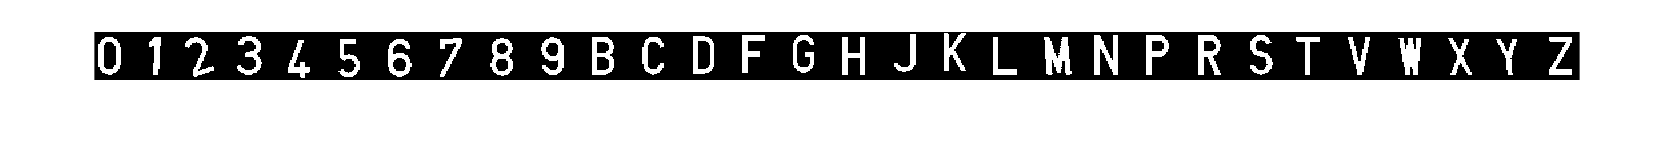

I = rgb2gray(imread('Joc_de_caracters.jpg'));
BI = I < 128; % lletres estan en negre
CC = bwconncomp(BI);
props = regionprops(CC,'Area','MajorAxisLength','MinorAxisLength');
X = [props.Area; props.MajorAxisLength; props.MinorAxisLength;]';
OUT = {'0' '1' '2' '3' '4' '5' '6' '7' '8' '9' 'B' 'C' 'D' 'F' 'G' 'H' 'J' 'K' 'L' 'M' 'N' 'P' 'R' 'S' 'T' 'V' 'W' 'X' 'Y' 'Z'};
Classifier = TreeBagger(100,X,OUT');
I = rgb2gray(imread('Joc_de_caracters_deformats.jpg'));
BI = I < 128; % separem el background
figure;imshow(BI);

BI  = imopen(BI, strel('disk', 1));
CC = bwconncomp(BI);

props = regionprops(CC,'Area','MajorAxisLength','MinorAxisLength');
X = [props.Area; props.MajorAxisLength; props.MinorAxisLength;]'; 
[label,score] = predict(Classifier,X);

% mostrem el resultat mes probable i la seva puntuació (score)
table(Classifier.ClassNames,label,max(score,[],2),'VariableNames',{'Name','Label','Score'})

ans = 30×3 table
    Name     Label    Score
    _____    _____    _____

    {'0'}    {'0'}    0.62 
    {'1'}    {'1'}    0.54 
    {'2'}    {'2'}    0.43 
    {'3'}    {'5'}    0.22 
    {'4'}    {'4'}     0.6 
    {'5'}    {'5'}    0.47 
    {'6'}    {'6'}     0.6 
    {'7'}    {'7'}    0.68 
    {'8'}    {'8'}    0.63 
    {'9'}    {'9'}    0.62 
    {'B'}    {'B'}    0.62 
    {'C'}    {'C'}    0.62 
    {'D'}    {'D'}    0.55 
    {'F'}    {'F'}    0.47 
    {'G'}    {'G'}    0.57 
    {'H'}    {'H'}    0.46 
